## Topic 1: Multicollinearity in General Linear Model (GLM)

### 1. Collinearity among regressors

- Definition: Collinearity

    Collinearity refers to a situation in linear regression models where some of the independent variables are highly correlated. This correlation can be problematic as it undermines the statistical significance of an independent variable.

    In the context of functional Magnetic Resonance Imaging (fMRI) in psychology, multicollinearity can arise when multiple brain regions are analyzed simultaneously. The BOLD (Blood Oxygen Level Dependent) signals in these regions might be correlated, leading to multicollinearity.

- Example (MATLAB Code)

    To simulate collinearity, we'll generate some correlated data and analyze its impact. We'll use MATLAB to create a simple linear regression model with multicollinear predictors.

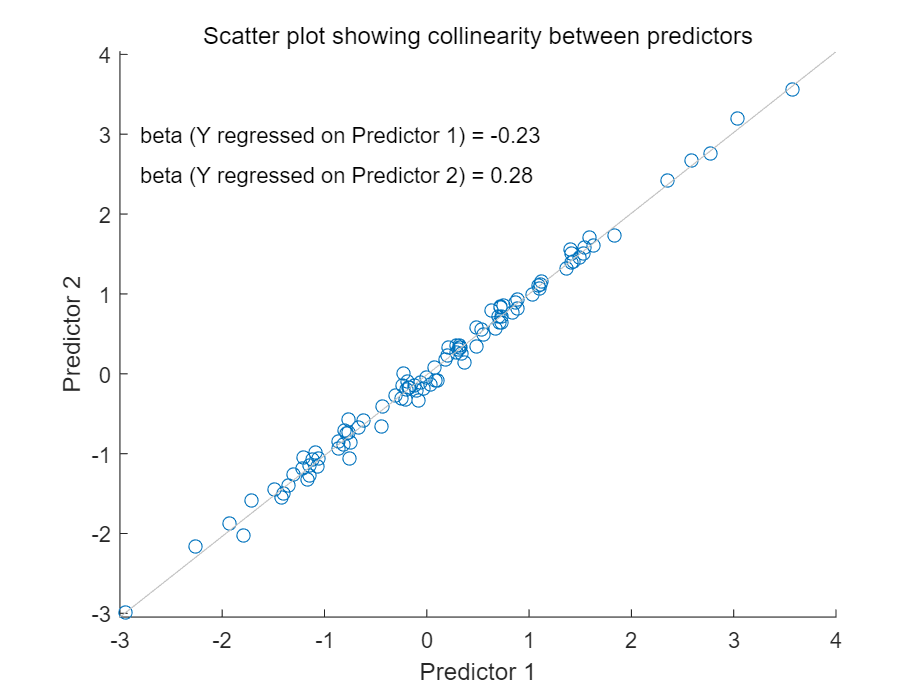

% Generating correlated data
rng('default'); % For reproducibility
X = randn(100,2);
X(:,2) = X(:,1) + randn(100,1)*0.1; % Introducing collinearity

% Performing linear regression
b_addcolin = regress(randn(100,1), [X ones(100,1)]);

% Plotting the data to show correlation
scatter(X(:,1), X(:,2));
xlabel('Predictor 1');
ylabel('Predictor 2');
title('Scatter plot showing collinearity between predictors');
lsline()
text(-2.8,3,sprintf('beta (Y regressed on Predictor 1) = %.2f',b_addcolin(1)))
text(-2.8,2.5,sprintf('beta (Y regressed on Predictor 2) = %.2f',b_addcolin(2)))

- Influences on your model

    Multicollinearity can inflate the variance of the coefficient estimates and make the estimates very sensitive to changes in the model. It can also make it difficult to determine the individual effect of correlated predictors.

### 2. Collinearity and Rank Deficient

- Definition: Rank of a Design Matrix

    The rank of a design matrix in a GLM refers to the maximum number of linearly independent column vectors in the matrix. If the rank is less than the number of columns, the matrix is said to be rank deficient, indicating the presence of multicollinearity.

- Example (MATLAB Code)

    We can check the rank of a matrix to determine if it's rank deficient. Here's how you can do it in MATLAB:

% Checking the rank of the design matrix
rank_X = rank(X);

% Displaying rank of the matrix
disp(['Rank of the matrix: ', num2str(rank_X)]);

Rank of the matrix: 2


- How to avoid it? Orthogonalizing

    One way to deal with multicollinearity is to orthogonalize the predictors. This involves making the predictors perpendicular to each other in the geometric space, which removes the correlation between them.

- Orthogonalizing: The Principle

    Orthogonalization in the context of regression analysis refers to the process of converting a set of correlated variables into a set of uncorrelated variables. This is achieved by transforming the original variables into a new set of variables that are orthogonal (perpendicular) to each other in a multi-dimensional space.

    The process of orthogonalization can be achieved through various methods, one of the most common being Singular Value Decomposition (SVD). SVD is a technique in linear algebra that decomposes a matrix into three other matrices, symbolized as U, Σ, and V^T.

    In the context of multicollinearity, SVD helps in identifying the linearly independent components of the predictors. By keeping only these components, we effectively remove the correlated parts, thereby reducing multicollinearity.

When we perform Singular Value Decomposition (SVD) on a matrix $X$, it can be expressed as $X = U\Sigma V^T
$.

$U$and $V$are orthogonal matrices, and $\Sigma
$ is a diagonal matrix.

The columns of $U$(left singular vectors) are orthogonal to each other and represent the orthogonalized version of the columns in $X$.

By selecting the first few columns of $U$corresponding to the non-zero singular values in $\Sigma
$, we obtain a set of orthogonal predictors.

- MATLAB Code for Orthogonalizing:

% Orthogonalizing the predictors
[U,~,~] = svd(X, 'econ');
X_orthogonal = U(:,1:rank_X);

% New regression with orthogonal predictors
b_orthogonal = regress(randn(100,1), X_orthogonal);